Ashlynn Steeves, V00850631 

ECE 485, Assignment 6 

% Load provded data 
load('Assignment6_2020_Data.mat')

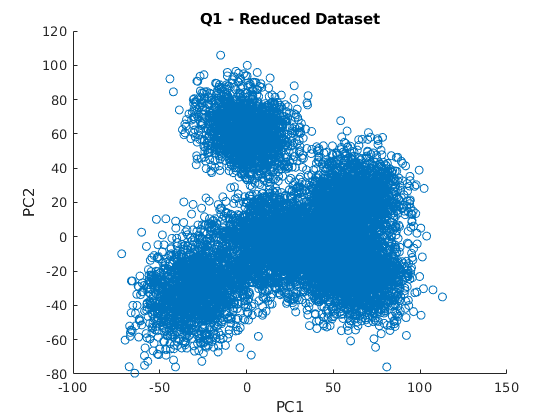

% Q1 - Use PCA to reduce the dataset to 2 dimensions
data_cov = cov(data); % Generate covariance matrix of provided dataset
[V, D] = eig(data_cov); % D is a diagonal matrix of eigenvalues, V is a matrix whose columns are the corresponding right eigenvectors

% Soring eigenvalues (and corresponding eigenvectors) into ascending order     
[~, ind] = sort(diag(D));
D_sorted = D(ind, ind);
V_sorted = V(:, ind);

% Since we want to reduce to 2 dimension, take the eigenvectors corresponding to the 2 largest eigenvalues 
projection_matrix = [V(:,length(D_sorted))  V(:,length(D_sorted)-1)];

% Generating reduced dataset by multiplying original dataset by the projection matrix
new_data = data*projection_matrix;

% Clearing some of the larger variables so my computer stops crying 
clear data D V D_sorted V_sorted projection_matrix d ind data_cov

% Plotting reduced data as a visual aid
scatter(new_data(:,1), new_data(:,2))

xlabel("PC1");
ylabel("PC2");
title("Q1 - Reduced Dataset")

% Generating some data about the bounds of the reduced dataset 
x1_max = ceil(max(new_data(:,1))); x1_min = floor(min(new_data(:,1))); % Range of PC1 data
x2_max = ceil(max(new_data(:,2))); x2_min = floor(min(new_data(:,2))); % Range of PC2 data 

x1_range = [x1_min:3:x1_max]; % Used in plotting
x2_range = [x2_min:3:x2_max]; % Used in plotting

% Q2 - Apply EM to provide an estimated pdf of the reduced data 
n = 5; % number of classes 

% Initializing the prior probability of each class to 1/5
% Each row corresponds to the prior of a given class
priors_q2 = [1/n ; 1/n; 1/n; 1/n; 1/n];

% Initializing means (really wanted to avoid hard coding these but alas, these are some general guesses from the plot of new_data)
% Each row corresponds to the mean of a given class
mus_q2 = [-30 -30; 25 0; 0 60; 60 -20; 70 20];

% Initializing covariances 
covs_q2 = {[1 0; 0 1];[1 0; 0 1];[1 0; 0 1];[1 0; 0 1];[1 0; 0 1];};

% Initializing a matrix of zeros where each row represents a point in the dataset 
% and each column a class, the cell being the probability that point is in that class
prob_matrix_xgc_q2 = zeros(length(new_data), n);

% Initializing a zero matrix of priors 
prob_matrix_cgx_q2 = zeros(length(new_data), n);

% Running 15 itterations of EM, this will take a moment
for k = 1:15
    
    % This for loop simply generates the matrix of probablities that a is in a given class
    % c = class 
    for c=1:n
        % Computing some values that remain the same for the entire class so they are computed 5 times not 50000 times 
        sigma = covs_q2{c}; 
        sigma_I = inv(sigma);
        xi_uc = new_data - mus_q2(c,:);
        norm = (sqrt(2*pi*det(sigma)))^-1;
        % Filling in said matrix 
        for i = 1:length(new_data)
            prob_matrix_xgc_q2(i,c) = norm*exp(-0.5*xi_uc(i,:)*sigma_I*xi_uc(i,:)');
        end
    end 
    
    % Itterating through classes again to generate new data based on the probablities that eacg point belongs to a given class
    for c = 1:n 
        
        % Generating a matrix of probablities of a class given a point 
        num = prob_matrix_xgc_q2(:,c)*priors_q2(c);
        den = sum(prob_matrix_xgc_q2'.*priors_q2);
        prob_matrix_cgx_q2(:,c) = num./den';
        
        % Using those probabilites to generate new estimates of the covariance of each class 
        % Each line here represents the calculations for one cell in the covariance matrix
        covs_q2{c}(1,1) = sum(((prob_matrix_cgx_q2(:,c)/(length(new_data)*priors_q2(c))).*(new_data(:,1)-mus_q2(c,1)).*(new_data(:,1)-mus_q2(c,1))),'omitnan');
        covs_q2{c}(1,2) = sum(((prob_matrix_cgx_q2(:,c)/(length(new_data)*priors_q2(c))).*(new_data(:,1)-mus_q2(c,1)).*(new_data(:,2)-mus_q2(c,2))),'omitnan');
        covs_q2{c}(2,1) = sum(((prob_matrix_cgx_q2(:,c)/(length(new_data)*priors_q2(c))).*(new_data(:,2)-mus_q2(c,2)).*(new_data(:,1)-mus_q2(c,1))),'omitnan');
        covs_q2{c}(2,2) = sum(((prob_matrix_cgx_q2(:,c)/(length(new_data)*priors_q2(c))).*(new_data(:,2)-mus_q2(c,2)).*(new_data(:,2)-mus_q2(c,2))),'omitnan');
        
        % Using those probabilites to generate new estimates of the means of each class 
         mus_q2(c,1) = sum(((prob_matrix_cgx_q2(:,c)/(length(new_data)*priors_q2(c))).*new_data(:,1)),'omitnan');
         mus_q2(c,2) = sum(((prob_matrix_cgx_q2(:,c)/(length(new_data)*priors_q2(c))).*new_data(:,2)), 'omitnan');
         
         % Using those probabilites to generate new estimates of the prior probability of each class 
         priors_q2(c) = (1/length(new_data))*sum(prob_matrix_cgx_q2(:,c),'omitnan');
        
    end
end 

% If the values output here are summarized below but if you want to see them feel free to remove the ;
mus_q2; 
priors_q2;
covs_q2{1};
covs_q2{2};
covs_q2{3}; 
covs_q2{4};
covs_q2{5};


Based on 15 itterations of the Expectation Maximization algorithm our pdf is a sum of 5 gaussians with the following characteristics:

1 - normilization constant = 0.1789,  mean = [-27.5, -30.5] , covariance = [243.7, 64.4; 64.4, 230.2]

2- normilization constant = 0.2939, mean = [26.5, -4.3] , covariance = [ 429.8 -42.6; -42.6, 194.7] 

3- normilization constant = 0.1624, mean = [-0.2, -61.4] , covariance = [ 185.9, -40.8; -40.8, 161.6]

4- normilization constant = 0.2054, mean = [62.3, -20.1] , covariance = [ 199.3, -37.6; -37.6, 173.2] 

5- normilization constant = 0.1593, mean = [62.2, 22.6] , covariance = [ 183.3, -3.1; -3.1, 164.9] 

% Q3 - Produce a Parzen window estimate of the datas pdf 
hn = 3; % Ran this a couple times and found an h that was suitably smooth

% Because of how I did this assignment I know know that we will need this
% matrix of pdf values for the surface and contour plots so i am writing into it directly  
Z_pzn = zeros(length(x2_range),length(x1_range));

% Itterating through the matrix, this will take a moment 
for i = 1:length(x1_range)
    for j = 1:length(x2_range)
        % Calls the parzan window function (at the bottom of this script
        % because matlab. This part specifically...not the fastest thing 
        Z_pzn(j,i) = pzn_window([x1_range(i) x2_range(j)], hn, new_data);
    end
end 


Q4 - Compare the Two Methods used to Generate a PDF of the Data

 In question 2 we derived a probability density function from the data as the sum of 5 gaussians, hich were generated using the expectation maximization algorithm. This method produced a smoothed pdf well fit to the data that is unlikley to cause issues with overfitting as it does not place much weight on individual points in the dataset. However this pdf is generated based on assumptions about the underlying data, which may or may not be accurate. 

In question 3 we used a parzen window algorithm to generate a probability density function directly from the dataset. This pdf varies a fair amount depending on the chosen value for the bandwidth (hn), this could lead to problems with over or underfittig the distribution to the dataset.  However, unlike the methods used in question 2, the parzan window approach does not make any assumptions about the underlying dataset in order to generate a probability density function. 

For this dataset I believe the methods used in question 2 to generate a probability density function are best. This is because by simply looking at the plot of the data we obtain after applying PCA the assumption that this data came from 5 seperate gaussians is quite plausable. On the contrary, the h value used in question 3 was chosen fairly randomly and therefore is subject to a larger error rate than that introduced by the methods in question 2. 

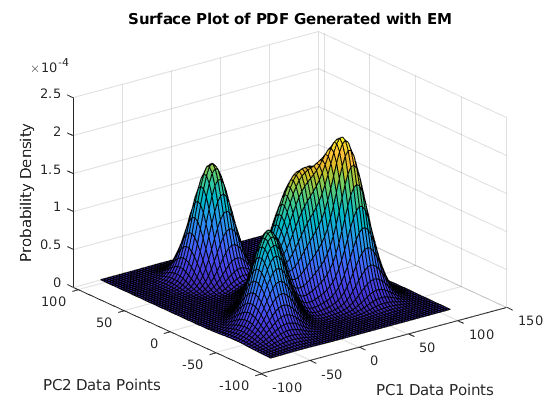

% Q5 - EM Plots 
Z_EM = zeros(length(x2_range),length(x1_range));

% Generating the matrix of pdf values for the sum of gaussians derived in
% Q2
for i = 1:length(x1_range)
    for j = 1:length(x2_range)
        c1_gaus = mvnpdf([x1_range(i) x2_range(j)], mus_q2(1,:), covs_q2{1}); 
        c2_gaus = mvnpdf([x1_range(i) x2_range(j)], mus_q2(2,:), covs_q2{2});
        c3_gaus = mvnpdf([x1_range(i) x2_range(j)], mus_q2(3,:), covs_q2{3});
        c4_gaus = mvnpdf([x1_range(i) x2_range(j)], mus_q2(4,:), covs_q2{4});
        c5_gaus = mvnpdf([x1_range(i) x2_range(j)], mus_q2(5,:), covs_q2{5});
        Z_EM(j,i) = (priors_q2(1)*c1_gaus)+(priors_q2(2)*c2_gaus)+(priors_q2(3)*c3_gaus)+(priors_q2(4)*c4_gaus)+(priors_q2(5)*c5_gaus);
    end 
end 

surf(x1_range, x2_range, Z_EM)
title('Surface Plot of PDF Generated with EM')
xlabel("PC1 Data Points")
ylabel("PC2 Data Points")
zlabel("Probability Density")

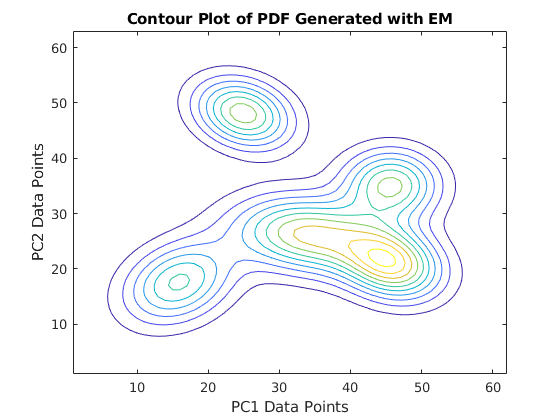

contour(Z_EM)
title('Contour Plot of PDF Generated with EM')
xlabel("PC1 Data Points")
ylabel("PC2 Data Points")

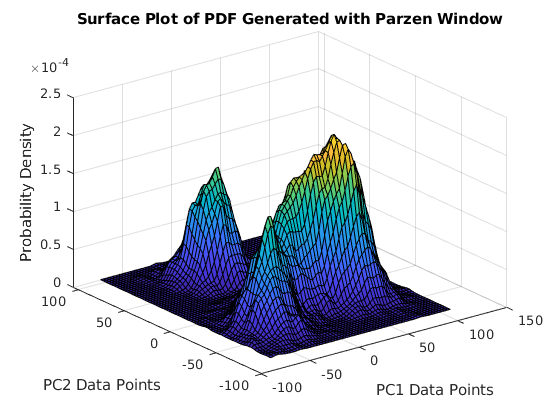

% Q5 - Parzen Window Plots 
surf(x1_range, x2_range, Z_pzn)
title('Surface Plot of PDF Generated with Parzen Window')
xlabel("PC1 Data Points")
ylabel("PC2 Data Points")
zlabel("Probability Density")

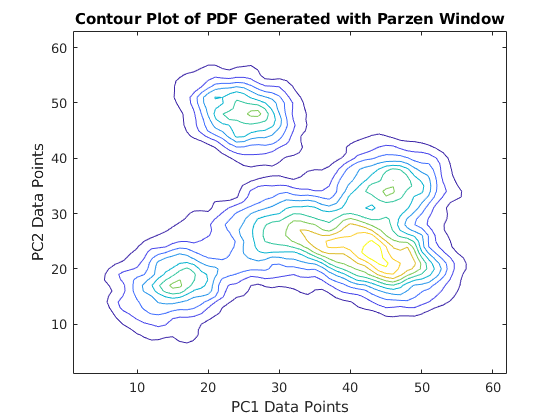

contour(Z_pzn)
title('Contour Plot of PDF Generated with Parzen Window')
xlabel("PC1 Data Points")
ylabel("PC2 Data Points")

% Function used to generate the Parzen Window pdf 
% Were using a spherical gaussian here bc the distribution to be used wasnt
% specified and I already had this function written from A5 

function[pzn_density] = pzn_window(pt, hn, training_data)
    pzn_density = 0; 
    [r,d] = size(training_data);
    % Pre computing x-xi 
    y = pt-training_data;
    % Computing the sum section of pn(x)
    for i = 1:r
        pzn_density = pzn_density + (2*pi)^(-d/2)*hn^(-d)*exp(-y(i,:)*y(i,:)'/(2*hn^2));
    end 
    % Noramalizing
    pzn_density = pzn_density/r;  
end 
